
load('occupancy_map_data50.mat')
map = Map

map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

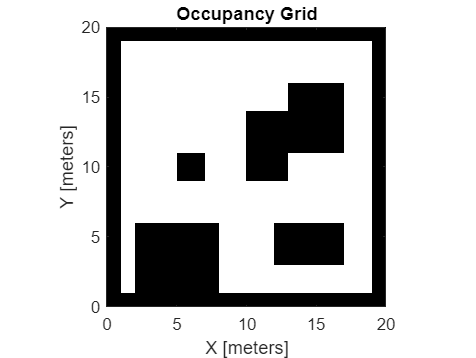

load ("occupancy_map50.mat")
oMap = occupancyMap(omap);
show(oMap)

GW = createGridWorld(size(Map,1),size(Map,2), "Kings")

GW =   GridWorld with properties:

                GridSize: [20 20]
            CurrentState: "[1,1]"
                  States: [400×1 string]
                 Actions: [8×1 string]
                       T: [400×400×8 double]
                       R: [400×400×8 double]
          ObstacleStates: [0×1 string]
          TerminalStates: [0×1 string]
    ProbabilityTolerance: 8.8818e-16



ObstacleData = []


ObstacleData =

     []




for i = 1:size(Map,1)
    for j = 1:size(Map,2)
        if Map(i, j) == 1
            obstacle = ["["+ num2str(i)+","+ num2str(j)+"]"];
            ObstacleData = [ObstacleData; obstacle];
        end    
    end
end

ObstacleData

ObstacleData = 160×1 string array
    "[1,1]"
    "[1,2]"
    "[1,3]"
    "[1,4]"
    "[1,5]"
    "[1,6]"
    "[1,7]"
    "[1,8]"
    "[1,9]"
    "[1,10]"
    "[1,11]"
    "[1,12]"
    "[1,13]"
    "[1,14]"
    "[1,15]"
    "[1,16]"
    "[1,17]"
    "[1,18]"
    "[1,19]"
    "[1,20]"
    "[2,1]"
    "[2,3]"
    "[2,4]"
    "[2,5]"
    "[2,6]"
    "[2,7]"
    "[2,8]"
    "[2,20]"
    "[3,1]"
    "[3,3]"



GW.ObstacleStates = ObstacleData;
GW.ObstacleStates

ans = 160×1 string array
    "[1,10]"
    "[1,11]"
    "[1,12]"
    "[1,13]"
    "[1,14]"
    "[1,15]"
    "[1,16]"
    "[1,17]"
    "[1,18]"
    "[1,19]"
    "[1,1]"
    "[1,20]"
    "[1,2]"
    "[1,3]"
    "[1,4]"
    "[1,5]"
    "[1,6]"
    "[1,7]"
    "[1,8]"
    "[1,9]"
    "[10,11]"
    "[10,12]"
    "[10,13]"
    "[10,1]"
    "[10,20]"
    "[10,6]"
    "[10,7]"
    "[11,11]"
    "[11,12]"
    "[11,13]"


GW.CurrentState = '[8,5]';


for i=1:size(GW.States,1)
    if GW.States(i) == GW.CurrentState
        startState = i
    end
end

startState = 88



GW.TerminalStates = '[17,17]';

%updateStateTranstionForObstacles(GW);
nS = numel(GW.States);
nA = numel(GW.Actions);

GW.R = -1*ones(nS,nS,nA);
GW.R(:,state2idx(GW,GW.ObstacleStates),:) = -50

GW =   GridWorld with properties:

                GridSize: [20 20]
            CurrentState: "[8,5]"
                  States: [400×1 string]
                 Actions: [8×1 string]
                       T: [400×400×8 double]
                       R: [400×400×8 double]
          ObstacleStates: [160×1 string]
          TerminalStates: "[17,17]"
    ProbabilityTolerance: 8.8818e-16


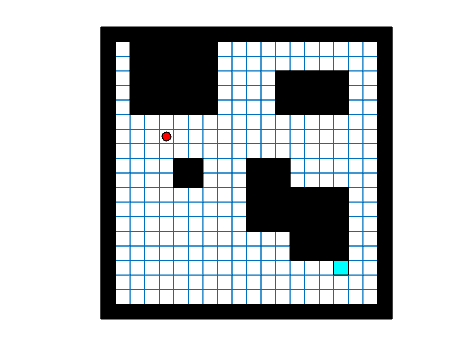

GW.R(:,state2idx(GW,GW.TerminalStates),:) = 10;
env = rlMDPEnv(GW);
plot(env)

startState

startState = 88

env.ResetFcn = @() startState; %Itt be kell állítani, hogy melyik a kezdő állapot
%rng(0)

qTable = rlTable(getObservationInfo(env), ...
    getActionInfo(env));

qFcnAppx = rlQValueFunction(qTable, ...
    getObservationInfo(env), ...
    getActionInfo(env));

qAgent = rlQAgent(qFcnAppx);
qAgent.AgentOptions.EpsilonGreedyExploration.Epsilon = .4;
qAgent.AgentOptions.CriticOptimizerOptions.LearnRate = 0.1;


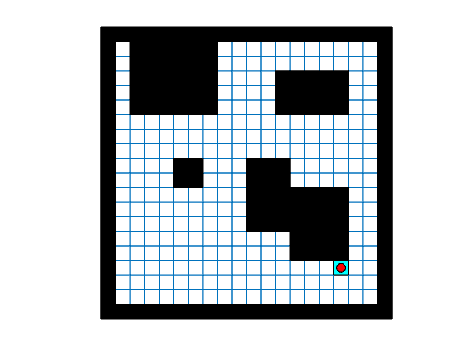

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 500;
trainOpts.MaxEpisodes= 200;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 1000;
trainOpts.ScoreAveragingWindowLength = 30;


trainingStats = train(qAgent,env,trainOpts);

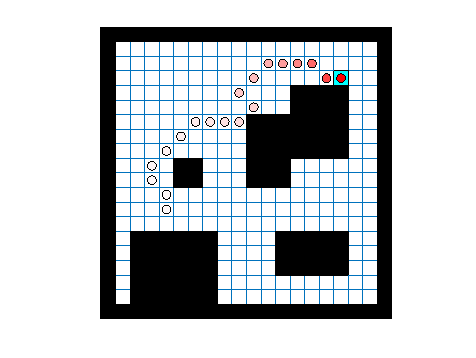

exp = struct with fields:
       Observation: [1×1 struct]
            Action: [1×1 struct]
            Reward: [1×1 timeseries]
            IsDone: [1×1 timeseries]
    SimulationInfo: [1×1 struct]



plot(env)
set(gca, 'YDir','reverse')
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;
exp = sim(qAgent,env)

%Megvagy te geci

x = [];
y = [];

for i = 1:size(exp.Observation.MDPObservations.Data,3)
    data = exp.Observation.MDPObservations.Data(i);
    state = env.Model.States(data);
    matrix = str2num(state);
    x = [x;matrix(:,2)];
    y = [y;matrix(:,1)];
end

x

x =      5
     5
     4
     4
     5
     6
     7
     8
     9
    10


y

y =      8
     9
    10
    11
    12
    13
    14
    14
    14
    14


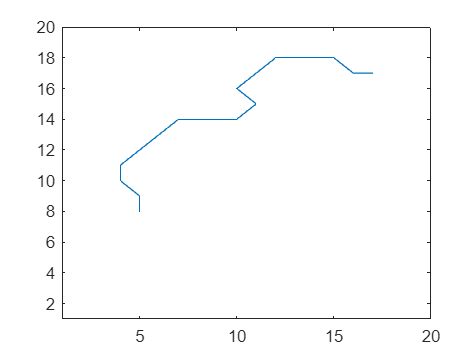

figure
plot(x,y)
axis([1 20 1 20])


%Meg kell csinálni a teljes Dubins smoothing connection-őket

dubConnObj = dubinsConnection;
dubConnObj.MinTurningRadius = 0.1

dubConnObj =   dubinsConnection with properties:

    DisabledPathTypes: {}
     MinTurningRadius: 0.1000
         AllPathTypes: {'LSL'  'LSR'  'RSL'  'RSR'  'RLR'  'LRL'}


allPose = [];

size(x,1)

ans = 19

startange = 0

startange = 0


for i=1:size(x,1)-1
    tavolsag_x = x(i+1) - x(i);
    tavolsag_y = y(i+1) - y(i);

    degree = atan2d(tavolsag_y,tavolsag_x);
    R = deg2rad(degree);

    startData = [x(i) y(i) startange];
    enddata = [x(i+1) y(i+1) R];
    startange = R;
    [pathSegObj,pathCosts] = connect(dubConnObj,startData,enddata);
    length = pathSegObj{1}.Length;
    poses = interpolate(pathSegObj{1},0:0.05:length);

    allPose = [allPose; [poses(:,1), poses(:,2)]];
end



allPose

allPose =     5.0000    8.0000
    5.0479    8.0122
    5.0841    8.0460
    5.0997    8.0929
    5.0994    8.1112
    5.0958    8.1427
    5.0902    8.1924
    5.0846    8.2421
    5.0791    8.2918
    5.0735    8.3414


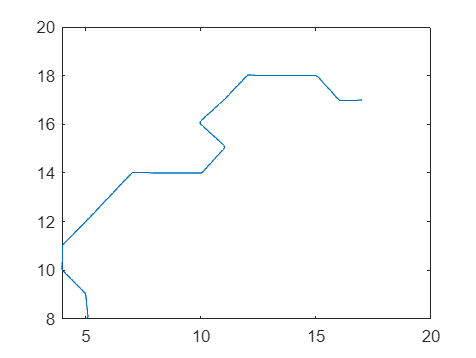

plot(allPose(:,1), allPose(:,2))

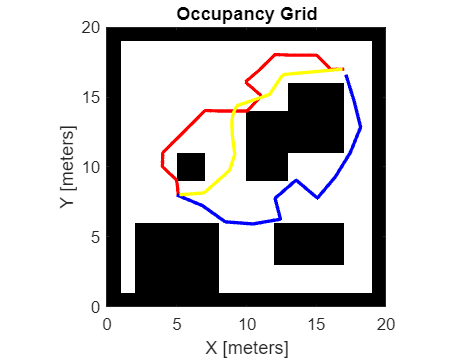


figure
show(oMap)
hold on
plot(allPose(:,1),allPose(:,2),'r-','LineWidth',2)
plot(pathObj.States(:,1),pathObj.States(:,2),'b-','LineWidth',2)
plot(allVFHdata(:,1),allVFHdata(:,2),'y-','LineWidth',2)